### This experiment corresponds to the Section 5.3 of the Thesis

For the smooth running of the experiment make sure to have python (version 2.7) installed and then also have the package 

installed mentioned in the file BEAY_IN_OUT1.

Determine and give input to the following for the Parameters and response data ids. The conversion of the data to respective format

 will be then done for the compatibility of the corresponding software**.** 

IPs_IDs1 = [32866       32886       32870       32874       32882       32846       32850       32878       32854   32858       32890       32862];


MP_IDs_normal_current_density = [14390, 7400, 4060, 16000, 19860, 23802];


IDs = {py.list(IPs_IDs1), py.list(MP_IDs_normal_current_density)};


IDs_mat_arr = {IPs_IDs1, MP_IDs_normal_current_density};


IDs_types = {'Internal Points', 'Mesh Points'};


calib_data_type = {'voltage', 'normal current density'};

source_parameters = {'BARE','Zone1'};

parameters= {'BARE','Zone1'};

x0 = [1.75, 3];

%x0 = [2.25 3];

**Navigate the Simulation related folder, the seed folder that contains the BEASY simulation input file and **

**collection dir will be holding the simulation results during the experimentation process.**

root_folder = 'D:\DOE_nd_data_generation\Multilinear_pol_curves\Parameter_BARE_Zone1';

simulation_seed_folder = fullfile(root_folder, 'Initial_files');

collection_dir = fullfile(root_folder, 'Simulation_results_fminunc');

files_name = 'BU_Jacket_newCurves';

The following simulation folder holds the response data for the initial guess (x0) of parameter value. 

initial_folder = '';
for i = 1:length(parameters)
    initial_folder =   strcat(initial_folder, parameters{i},'_', num2str(x0(i), '%.4f'));
    if i~=length(parameters)
        initial_folder = strcat(initial_folder, '_');
    end
end

initial_dir = fullfile(collection_dir, initial_folder);

if ~isfolder(initial_dir)
    initial_dict = py.BEASY_IN_OUT1.get_response_data_for_IDs_and_input_parameters( parameters, ...
        x0, simulation_seed_folder, collection_dir,  py.list(calib_data_type), py.list(IDs), ...
        py.list(IDs_types));
    initial_data = convert_pydict2data(initial_dict,1);
else

    initial_dict = py.BEASY_IN_OUT1.get_output_data_for_IDs_from_simulation_folder(initial_dir, ...
        files_name, py.list(calib_data_type),  py.list(IDs), py.list(IDs_types));
    initial_data = convert_pydict2data(initial_dict,0);
end

#### Loading the Calibration data. 

The data given in excel file with the data associated to the IDs mentioned above can be directly read. In this case as the data is

 obtained from an artifical simulatin with some noise introduction after having the simulation data.)

calib_dir = fullfile(root_folder,'Calibration_data');

calib_data_file_err_inc = 'data_with_error_MP_IDs_Ncd.xlsx';

%%{
if ~isfile(fullfile(calib_dir, calib_data_file_err_inc))
    all_position_dict = py.BEASY_IN_OUT1.get_output_data_for_IDs_from_simulation_folder(calib_dir, ...
        files_name, py.list(calib_data_type),  py.list(IDs), py.list(IDs_types));
    all_position_data = convert_pydict2data(all_position_dict,0);
    introduce_error_and_write_file( {IPs_IDs1.', MP_IDs_normal_current_density.'}, ...
        all_position_data, calib_dir, calib_data_file_err_inc,1);
end
%model_out = output_from_surrogates([2.0, 3.0], surrogates, [17,6]);
%}
calib_data_inc_error = data_from_tables2(fullfile(calib_dir, calib_data_file_err_inc), ...
    IDs_mat_arr, 3);
calib_data_no_error = py.BEASY_IN_OUT1.get_output_data_for_IDs_from_simulation_folder(calib_dir, ...
    'BU_Jacket_newCurves', py.list(calib_data_type),  py.list(IDs), py.list(IDs_types));
calib_data_no_error = convert_pydict2data(calib_data_no_error,0);

The following plot is to analyse the difference in calibration data against the response data from simulation with x0 parameter values

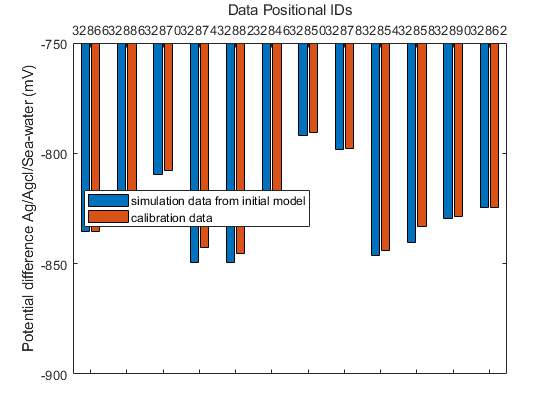


figure;

ax = gca;

data_index = 1;

difference_in_bar_chart(ax,initial_data{data_index}, calib_data_inc_error{data_index}, ...
    {'simulation data from initial model','calibration data'});
ylim([-900, -750])

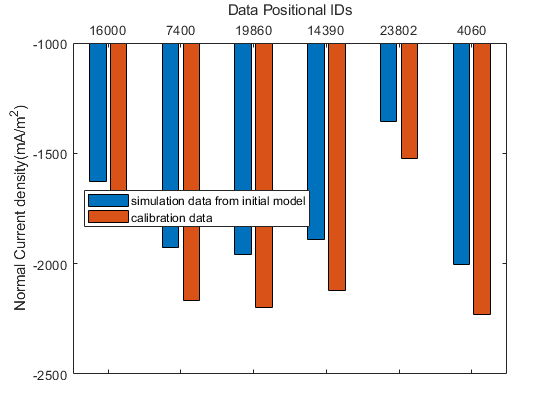


figure;

ax = gca;

data_index = 2;

difference_in_bar_chart(ax,initial_data{data_index}, calib_data_inc_error{data_index}, ...
    {'simulation data from initial model','calibration data'});
ylabel('Normal Current density(mA/m^2)')
ylim([-2500, -1000])

#### Optimisation with Minimisation for Best Parameter Finding. This part corresponds to the section 5.3.6 of the thesis 

#### and use the tool 'fminunc' for the optimisation

metric = 'nmsq';

obj_weightage = [0.6 0.3];
%obj_weightage = [2 1];
%obj_weightage = [1 0];
%obj_weightage = [1 5];
%obj_weightage = [1 10];
%obj_weightage = [1 2];

[xsol,fval,opt_data] = runfminunc(x0, parameters, calib_data_inc_error, simulation_seed_folder, collection_dir, ...

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           3        0.0175715                        0.0459
     1           6         0.015382              1         0.0285  
     2          15       0.00314909        1.84606         0.0297  

Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>


    metric, calib_data_type, IDs, IDs_types, obj_weightage);
%[xsol,fval,opt_data] = runfminunc(x0,source_parameters, parameters, calib_data_no_error, simulation_seed_folder, collection_dir, metric, calib_data_type, IDs, IDs_types, obj_weightage);
  
%Objective(x0,source_parameters, parameters,calib_data_no_error, simulation_seed_folder, collection_dir, metric, calib_data_type, IDs, IDs_types, obj_weightage)

                               
%repetitive_calibration_count = 2;

xsol

xsol =     2.0612    3.2494


opt_data

opt_data =     1.7500    3.0000
    1.7959    3.0145
    2.0612    3.2494


testing_par_value = xsol;

solution_folder = '';
for i = 1:length(parameters)
    solution_folder =   strcat(solution_folder, parameters{i},'_', num2str(testing_par_value(i), '%.4f'));
    if i~=length(parameters)
        solution_folder = strcat(solution_folder, '_');
    end
end
solution_colection_dir = fullfile(root_folder,'Solution_results');

solution_dir = fullfile(solution_colection_dir, solution_folder);

if ~isfolder(solution_dir)
    solution_dict = py.BEASY_IN_OUT1.get_response_data_for_IDs_and_input_parameters( py.list(parameters), ...
        py.list(testing_par_value), simulation_seed_folder, solution_colection_dir,  py.list(calib_data_type), py.list(IDs),  ...
        py.list(IDs_types));
    solution_data = convert_pydict2data(solution_dict,1);
else

    solution_dict = py.BEASY_IN_OUT1.get_output_data_for_IDs_from_simulation_folder(solution_dir, files_name, ...
        py.list(calib_data_type),  py.list(IDs), py.list(IDs_types));
    solution_data = convert_pydict2data(solution_dict,0);
end

%data from initial position

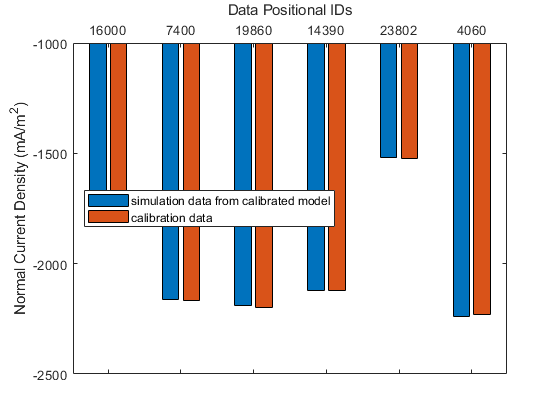

figure;

ax = gca;

data_index = 2;
difference_in_bar_chart(ax,solution_data{data_index}(1:end,:), ...
    calib_data_inc_error{data_index}(1:end,:),{'simulation data from calibrated model', ...
    'calibration data'});

%set(ax,'XAxisLocation','bottom');

if isequal(data_index, 2)
    %difference_in_bar_chart(ax,solution_data{data_count}, calib_data_inc_error{data_count},{'simulation data from calibrated model','calibration data', 'difference'});

    ylabel('Normal Current Density (mA/m^2)');
    ylim([-2500 -1000]);
else
    ylim([-860 -780]);
    ylabel(ax, 'Potential difference Ag/Agcl/Sea-water (mV)');
end

%ylabel('Z electric field (micro-V/m)');
%
%}